# Code Generation

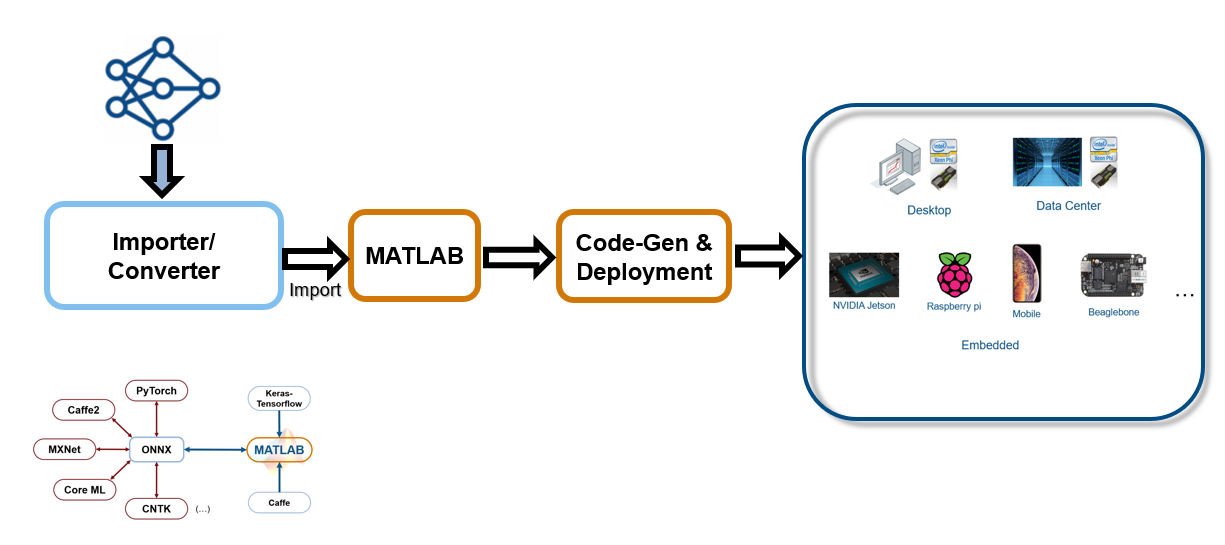

## Problem Description

This demo focuses on the workflow that covers importing a model from ONNX model zoo, using it to train a YOLOv2 object detector, and then target CUDA libraries for faster inference. (ResNet50 ONNX Model --> MATLAB --> YOLOv2 training --> Generate Code)

% doTraining = true;
% if ~doTraining && ~exist('yolov2ResNet50VehicleExample.mat','file')
%     % Download pretrained detector.
%     disp('Downloading pretrained detector (98 MB)...');
%     pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/yolov2ResNet50VehicleExample.mat';
%     websave('yolov2ResNet50VehicleExample.mat',pretrainedURL);
% end

doTraining = 0;
addpath(fullfile(pwd, 'HelperFilesAndFunctions'));

## **Load Dataset**

This example uses a small vehicle data set that contains 295 images. Each image contains one or two labeled instances of a vehicle. A small data set is useful for exploring the YOLO v2 training procedure, but in practice, more labeled images are needed to train a robust detector.

unzip vehicleDatasetImages.zip

% Load vehicle dataset ground truth.
data = load('vehicleDatasetGroundTruth.mat');
vehicleDataset = data.vehicleDataset;

Display first few rows of the data set.

vehicleDataset(1:4,:)

ans = 4×2 table
             imageFilename               vehicle   
    _______________________________    ____________

    'vehicleImages/image_00001.jpg'    [1×4 double]
    'vehicleImages/image_00002.jpg'    [1×4 double]
    'vehicleImages/image_00003.jpg'    [1×4 double]
    'vehicleImages/image_00004.jpg'    [1×4 double]


### Explore Data

Display one of the images from the data set to understand the type of images it contains.

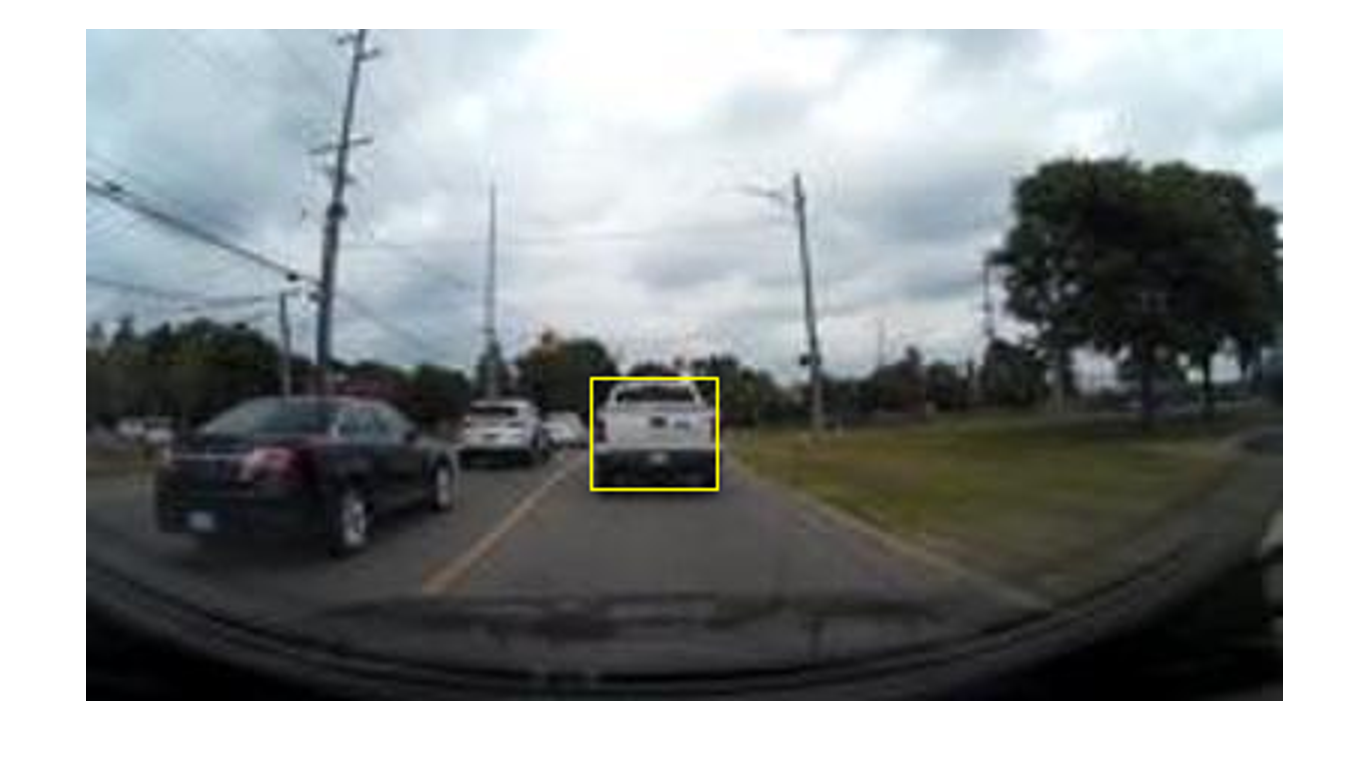

vehicleDataset.imageFilename = fullfile(pwd,vehicleDataset.imageFilename);

% Read one of the images.
I = imread(vehicleDataset.imageFilename{10});

% Insert the ROI labels.
I = insertShape(I,'Rectangle',vehicleDataset.vehicle{10});

% Resize and display image.
I = imresize(I,3);
imshow(I)

## Training and Test Set

Set random seed to ensure example training reproducibility.

Split the data set into a training set for training the detector, and a test set for evaluating the detector. Select 60% of the data for training. Use the rest for evaluation.

rng(0);

% Randomly split data into a training and test set.
shuffledIndices = randperm(height(vehicleDataset));
idx = floor(0.6 * length(shuffledIndices) );
trainingData = vehicleDataset(shuffledIndices(1:idx),:);
testData = vehicleDataset(shuffledIndices(idx+1:end),:);

## **Create a YOLO v2 Object Detection Network**

The YOLO v2 object detection network can be thought of as having two sub-networks. A feature extraction network, followed by a detection network.

The feature extraction network is typically a pretrained CNN (see [Pretrained Deep Neural Networks](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html) for more details). This example uses ResNet-50 for feature extraction. Other pretrained networks such as MobileNet v2 or ResNet-18 can also be used depending on application requirements. The detection sub-network is a small CNN compared to the feature extraction network and is composed of a few convolutional layers and layers specific for YOLO v2.

Use the `yolov2Layers` function to automatically modify a pretrained ResNet-50 network into a YOLO v2 object detection network. `yolov2Layers` requires you to specify several inputs that parameterize a YOLO v2 network.

First, specify the image input size and the number of classes. The image input size should be at least as big as the images in the training image set. In this example, the images are 224-by-224 RGB images.

imageSize = [224 224 3];

% Define the number of object classes to detect.
numClasses = width(vehicleDataset)-1;

Next, specify the size of the anchor boxes. The anchor boxes should be selected based on the scale and size of objects in the training data. You can [Estimate Anchor Boxes Using Clustering](https://www.mathworks.com/help/vision/ug/estimate-anchor-boxes-using-clustering-for-deep-learning.html) (Computer Vision Toolbox) to determine a good set of anchor boxes based on the training data. Using this procedure, the anchor boxes for the vehicle dataset are:

anchorBoxes = [
    43 59
    18 22
    23 29
    84 109
];

## Specify the backend network - Import ResNet-50 from ONNX model zoo

In this example, we'll use a pretrained [ResNet-50](https://s3.amazonaws.com/onnx-model-zoo/resnet/resnet50v1/resnet50v1.onnx) model as backend to train Yolov2. 

Explore a list of other models from [ONNX Model zoo](https://github.com/onnx/models) 

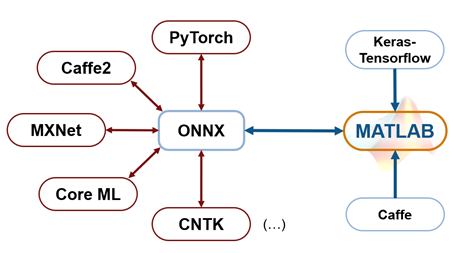

load classnames.mat
baseNetwork = importONNXNetwork('model.onnx', 'OutputLayerType','classification','classNames', classNames);

%baseNetwork = load('resNet50ONNX.mat')

Specify the feature extraction layer. featureLayer = 'node_140'; % use this when you're working with resnet50 pretrained model. This feature extraction layer outputs feature maps that are downsampled by a factor of 16. This amount of downsampling is a good trade-off between spatial resolution and the strength of the extracted features (features extracted further down the network encode stronger image features at the cost of spatial resolution). Choosing the optimal feature extraction layer requires empirical analysis and is another hyperparameter to tune.

*For models imported using importers, the layer names might be different. *

featureLayer = 'node_140'  ;
% Create the YOLO v2 object detection network. 
lgraph = yolov2Layers(imageSize,numClasses,anchorBoxes,baseNetwork,featureLayer);

## Train YOLO v2 Object Detector

To use the `trainYOLOv2ObjectDetector` function, set `doTraining` to true. Otherwise, load a pretrained detector.

Training this network took approximately 5 minutes using this setup on a NVIDA™  Titan X GPU. Training time varies depending on the hardware you use.

if doTraining
    
   
    options = trainingOptions('sgdm', ...
        'MiniBatchSize', 16, ....
        'InitialLearnRate',1e-3, ...
        'MaxEpochs',10,...
        'CheckpointPath', tempdir, ...
        'Shuffle','every-epoch');    
    
    % Train YOLO v2 detector.
    [detector,info] = trainYOLOv2ObjectDetector(vehicleDataset,lgraph,options);
else
    % Load pretrained detector for the example.
    pretrained = load(fullfile('results','Yolov2UsingResNet50_ONNX.mat'));
    detector = pretrained.detector;
end

## Test the Model's accuracy

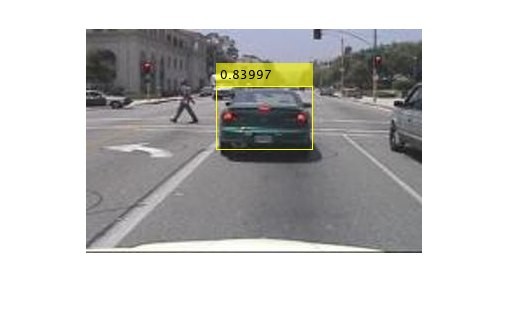

I = imread(testData.imageFilename{end});

% Run the detector.
[bboxes,scores] = detect(detector,I);

% Annotate detections in the image.
I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
imshow(I)

### **Evaluate Detector Using Test Set**

Evaluate the detector on a large set of images to measure the trained detector's performance.

The first step for detector evaluation is to collect the detection results by running the detector on the test set.

`Create a table to hold the bounding boxes, scores, and labels output by the detector. `

numImages = height(testData);
results = table('Size',[numImages 3],...
    'VariableTypes',{'cell','cell','cell'},...
    'VariableNames',{'Boxes','Scores','Labels'});

% Run detector on each image in the test set and collect results.
for i = 1:numImages
    
    % Read the image.
    I = imread(testData.imageFilename{i});
    
    % Run the detector.
    [bboxes,scores,labels] = detect(detector,I);
   
    % Collect the results.
    results.Boxes{i} = bboxes;
    results.Scores{i} = scores;
    results.Labels{i} = labels;
end

% Extract expected bounding box locations from test data.
expectedResults = testData(:, 2:end);

% Evaluate the object detector using average precision metric.
[ap, recall, precision] = evaluateDetectionPrecision(results, expectedResults);

### Evaluation Metric - Precision/ Recall Curve

The precision/recall (PR) curve highlights how precise a detector is at varying levels of recall. Ideally, the precision would be 1 at all recall levels. The use of additional layers in the network can help improve the average precision, but might require additional training data and longer training time.

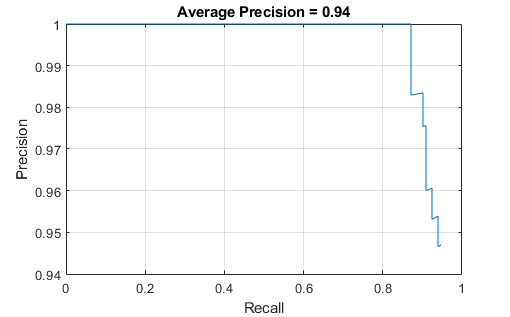

plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f', ap))

## Code Generation

### **Verify the GPU Environment**

Use the [`coder.checkGpuInstall`](https://www.mathworks.com/help/gpucoder/ref/coder.checkgpuinstall.html) function and verify that the compilers and libraries needed for running this example are set up correctly.

envCfg = coder.gpuEnvConfig('host');
envCfg.DeepLibTarget = 'cudnn';
envCfg.DeepCodegen = 1;
envCfg.Quiet = 1;
coder.checkGpuInstall(envCfg);

## **Run MEX Code Generation for 'yolov2_detect' Function**

cfg = coder.gpuConfig('mex');
cfg.TargetLang = 'C++';
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
codegen -config cfg yolov2_detect -args {ones(224,224,3,'uint8')} -report

Code generation successful: View report


## **Run the Generated MEX**

To generate CUDA code from the design file [yolov2_detect.m](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','yolov2_detect.m'))), create a GPU code configuration object for a MEX target and set the target language to C++. Use the [`coder.DeepLearningConfig`](https://www.mathworks.com/help/gpucoder/ref/coder.deeplearningconfig.html) function to create a `CuDNN` deep learning configuration object and assign it to the `DeepLearningConfig` property of the GPU code configuration object. Run the `codegen` command specifying an input of size [224,224,3]. This value corresponds to the input layer size of YOLOv2.

videoFile = 'highway_lanechange.mp4';
videoFreader = vision.VideoFileReader(videoFile,'VideoOutputDataType','uint8');
depVideoPlayer = vision.DeployableVideoPlayer('Size','Custom','CustomSize',[640 480]);

### Read the video input frame-by-frame and detect the vehicles in the video using the detector.

cont = ~isDone(videoFreader);
while cont
    I = step(videoFreader);
    in = imresize(I,[224,224]);
    out = yolov2_detect_mex(in);
    step(depVideoPlayer, out);
    cont = ~isDone(videoFreader) && isOpen(depVideoPlayer); % Exit the loop if the video player figure window is closed
end